# Ejercicio 1

## a)

function[Q,R] = qr1(A)
    % Tamaño de la matriz A 
    [m, n] = size(A); %m filas y n columnas
    
    % Inicializar Q con ceros y tamaño como A
    Q = zeros(m, n);  
    
    % Inicializar R de n x n
    R = zeros(n, n); 
    
    %Ciclo que recorre las columnas
    for j = 1:n
        % Tomar la columna j de A y la asigna a v_j
        vj = A(:, j);
        
        % Bucle interno para calcular las proyecciones
        % Note que cuando j=1 el ciclo va de 1:0, es decir no se ejecuta.
        for i = 1:j-1
    
            % Calcular r_ij, es producto interno
            R(i, j) = Q(:, i)' * A(:, j);
            
            % Modifica v_j restando la proyección de a_j en q_i
            vj = vj - R(i, j) * Q(:, i);
        end
        
        % Paso 3: calcula r_jj como la norma de v_j y normaliza para obtener q_j
        R(j, j) = norm(vj);
        Q(:, j) = vj / R(j, j);
    end
end


## b)

function[Q,R] = qr2(A)
    % Tamaño de la matriz A 
    [m, n] = size(A); %m filas y n columnas
    
    % Inicializar Q con ceros y tamaño como A
    Q = zeros(m, n);  
    
    % Inicializar R de n x n
    R = zeros(n, n);
    
    % Definir la matriz A igual a una V
    V = A;

    % Ciclo for que recorre columnas de v
    for i = 1:n
        
        % Llenar el valor r_ii
        R(i, i) = norm(V(:, i));

        % Llenar la columna q_i
        Q(:,i) = V(:, i)/R(i, i);

        % Ciclo for interno de las proyecciones
        for j = i+1:n

            % Llenar la fila de la triangular
            R(i, j) = Q(:, i)' * V(:, j);

            % Modifica v_j restando la proyección de a_j en q_i
            V(:, j) = V(:,j) - R(i, j) * Q(:, i);
        end
    end
end


## c)

function [Q, R] = qr3(A)
    [m, n] = size(A);        % Tamaño de la matriz A
    R = A;                   % Inicializamos R como una copia de A
    M = eye(m);              % Matriz identidad de m x m para construir Q
    
    for j = 1:n
        % Selecciona el vector x desde la fila j hasta m de la columna j de R
        x = R(j:m, j);
        
        % Construye el vector de Householder vj
        e1 = zeros(length(x), 1);
        e1(1) = 1;
        vj = sign(x(1)) * norm(x) * e1 + x;
        vj = vj / norm(vj);  % Normaliza vj
        
        % Actualiza R aplicando la transformación de Householder
        R(j:m, j:n) = R(j:m, j:n) - 2 * vj * (vj' * R(j:m, j:n));
        
        % Actualiza M aplicando la misma transformación para construir Q
        M(j:m, :) = M(j:m, :) - 2 * vj * (vj' * M(j:m, :));
    end
    
    % La matriz Q es la transpuesta de M
    Q = M';
end


## d)

### Cálculo de la factorización implementando los 3 algoritmos

format long

% Definición de dimensiones
m = 20; % m = n

% Generar matriz aleatoria
A = rand(m);

% Generar matriz identidad mxm
I = eye(m);

% Algoritmo 1
[Q1,R1] = qr1(A)

Q1 =    0.183242217753921  -0.025636422065451  -0.352651470586100   0.331938685304752   0.394776710664825   0.068030286861334   0.271950658569408   0.145780173820435  -0.205274066297329  -0.259072936975682   0.069488149687342  -0.000497063854503   0.080890816743304  -0.111732618629953  -0.083439162377984   0.367024198909059  -0.255301258460690   0.222302688173272  -0.267853088087812   0.120037451532712
   0.186936712599269   0.170718576649507  -0.126336909281979  -0.119337435101800   0.234202765628531  -0.016060650419205   0.203192165670268  -0.317386404164988  -0.174752733859348   0.491896325118829   0.229354044053507   0.121496983371856  -0.268729745532943  -0.262122443207429  -0.156606970398699  -0.291182874623014  -0.257732891032339   0.014847410440413   0.203645816648571   0.101767646257686
   0.351455863958444  -0.345029547841881   0.139000384476336   0.236081624135451  -0.243944003802141   0.156654184900817  -0.190144876540878   0.191173617201375   0.223038870392089   0.00883559

R1 =    2.663138246670700   2.394600405738687   2.498543055851519   1.424680701228067   2.246852782915857   2.108413692323447   2.661177111868072   2.123513669113505   2.104628764357265   2.130737893925251   1.913210192809083   1.975011491989568   2.033040287335995   1.933512079337664   1.765750203009843   1.923846693135973   2.184067424154128   2.159982231186834   1.564288067867043   2.167188384666069
                   0   1.919334918682500   0.367524729256336   0.517527290179470   0.995105336323957   0.137218567084587   0.442114930600643   0.570290641557724   0.155652176723225   0.906944441533246   0.429342503957864   0.305297737669894   0.685238617249694   0.347280642368949   1.118526142182070   0.991601523958836   0.795801935635867   0.396932762847122   0.583069393418754   0.859246671786752
                   0                   0   1.232834742595248   0.126573617405416   0.118252295043981   0.201127350567636   0.419065178161786   0.383973718263472   0.408243793467603   0.26171504

% Algoritmo 2
[Q2,R2] = qr2(A)

Q2 =    0.183242217753921  -0.025636422065451  -0.352651470586100   0.331938685304752   0.394776710664825   0.068030286861334   0.271950658569408   0.145780173820434  -0.205274066297329  -0.259072936975682   0.069488149687342  -0.000497063854504   0.080890816743304  -0.111732618629953  -0.083439162377984   0.367024198909059  -0.255301258460691   0.222302688173274  -0.267853088087802   0.120037451532731
   0.186936712599269   0.170718576649507  -0.126336909281979  -0.119337435101800   0.234202765628531  -0.016060650419205   0.203192165670268  -0.317386404164988  -0.174752733859347   0.491896325118829   0.229354044053507   0.121496983371856  -0.268729745532943  -0.262122443207428  -0.156606970398698  -0.291182874623014  -0.257732891032337   0.014847410440411   0.203645816648556   0.101767646257671
   0.351455863958444  -0.345029547841881   0.139000384476336   0.236081624135450  -0.243944003802141   0.156654184900817  -0.190144876540878   0.191173617201375   0.223038870392089   0.00883559

R2 =    2.663138246670700   2.394600405738687   2.498543055851519   1.424680701228067   2.246852782915857   2.108413692323447   2.661177111868072   2.123513669113505   2.104628764357265   2.130737893925251   1.913210192809083   1.975011491989568   2.033040287335995   1.933512079337664   1.765750203009843   1.923846693135973   2.184067424154128   2.159982231186834   1.564288067867043   2.167188384666069
                   0   1.919334918682500   0.367524729256336   0.517527290179470   0.995105336323957   0.137218567084587   0.442114930600642   0.570290641557724   0.155652176723225   0.906944441533245   0.429342503957863   0.305297737669894   0.685238617249694   0.347280642368948   1.118526142182070   0.991601523958836   0.795801935635866   0.396932762847122   0.583069393418753   0.859246671786752
                   0                   0   1.232834742595248   0.126573617405416   0.118252295043982   0.201127350567636   0.419065178161786   0.383973718263472   0.408243793467603   0.26171504

% Algoritmo 3
[Q3,R3] = qr3(A)

Q3 =   -0.183242217753921   0.025636422065452   0.352651470586100   0.331938685304752  -0.394776710664825  -0.068030286861334   0.271950658569408  -0.145780173820435  -0.205274066297329   0.259072936975682   0.069488149687341  -0.000497063854504  -0.080890816743305   0.111732618629952   0.083439162377984   0.367024198909059   0.255301258460691   0.222302688173273   0.267853088087805   0.120037451532730
  -0.186936712599269  -0.170718576649508   0.126336909281979  -0.119337435101800  -0.234202765628531   0.016060650419205   0.203192165670268   0.317386404164988  -0.174752733859348  -0.491896325118829   0.229354044053507   0.121496983371856   0.268729745532943   0.262122443207428   0.156606970398699  -0.291182874623014   0.257732891032338   0.014847410440411  -0.203645816648549   0.101767646257672
  -0.351455863958444   0.345029547841881  -0.139000384476335   0.236081624135450   0.243944003802141  -0.156654184900817  -0.190144876540878  -0.191173617201376   0.223038870392089  -0.00883559

R3 =   -2.663138246670700  -2.394600405738687  -2.498543055851519  -1.424680701228067  -2.246852782915858  -2.108413692323447  -2.661177111868072  -2.123513669113505  -2.104628764357265  -2.130737893925250  -1.913210192809083  -1.975011491989567  -2.033040287335996  -1.933512079337664  -1.765750203009843  -1.923846693135974  -2.184067424154128  -2.159982231186834  -1.564288067867043  -2.167188384666069
   0.000000000000000  -1.919334918682500  -0.367524729256336  -0.517527290179470  -0.995105336323957  -0.137218567084587  -0.442114930600642  -0.570290641557724  -0.155652176723225  -0.906944441533246  -0.429342503957864  -0.305297737669894  -0.685238617249694  -0.347280642368948  -1.118526142182070  -0.991601523958836  -0.795801935635867  -0.396932762847122  -0.583069393418753  -0.859246671786752
   0.000000000000000   0.000000000000000  -1.232834742595248  -0.126573617405416  -0.118252295043981  -0.201127350567636  -0.419065178161786  -0.383973718263472  -0.408243793467603  -0.26171504

### Cálculo de las normas con los Q y R de los algoritmos

#### Para el algoritmo 1:

Cálculo de $\| A - Q_1R_1 \|_2$

disp(norm(A - Q1 * R1))

     7.593833434274956e-16



Cálculo de $\| Q_1Q_1^T - I \|_2$

disp(norm(Q1 * Q1' - I))

     1.205141340744771e-13



#### Para el algoritmo 3:

Cálculo de $\| A - Q_2R_2\|_2$

disp(norm(A - Q2 * R2))

     7.402143115756298e-16



Cálculo de $\| Q_2Q_2^T - I \|_2$

disp(norm(Q2 * Q2' - I))

     1.512252993219856e-14



#### Para el algoritmo 2:

Cálculo de $\| A - Q_3R_3\|_2$

disp(norm(A - Q3 * R3))

     3.065714060388978e-15



Cálculo de $\| Q_3Q_3^T - I \|_2$

disp(norm(Q3 * Q3' - I))

     9.936569346476342e-16



### ¿Se cumple que A = QR?

En los 3 algoritmos se obtuvo que la difencia$\| A - QR\|_2$ es extremadamente pequeña, siendo casi nivel de precisión de máquina, por lo que se puede concluir que si satisfacen la propiedad.

### ¿Se cumple que Q es ortogonal?

De manera similar se obtuvo que la diferencia $\| QQ^T - I \|_2$ en los 3 algoritmos fue sumamente baja a nivel de precisión de máquina, por lo que se puede concluir que las matrices Q generadas son ortogonales.

## Determinar si algún algoritmo es mejor

%Función para ver el error pormedio de los 3 algoritmos y así hacer una
%comparación
function error_promedio = media(num_alg, A)

    %num_alg es 1 usa la funcion qr1, si es 2 usa qr2 y si es 3 usa qr3
    
    % Inicializar el vector para almacenar los resultados
    resultados = zeros(1, 100);
    
    for i = 1:100
        % Seleccionar la función correspondiente según el valor de num_alg
        if num_alg == 1
            [Q, R] = qr1(A);
        elseif num_alg == 2
            [Q, R] = qr2(A);
        elseif num_alg == 3
            [Q, R] = qr3(A);
        elseif num_alg == 4
            [Q, R] = qr(A);
        else
            error('El valor de num_alg debe ser 1, 2 o 3');
        end
        
        % Calcular el producto Q * R y almacenar el resultado en el vector
        resultados(i) = norm(A - Q * R, 'fro'); % Se guarda la norma de la diferencia
    end
    error_promedio = mean(resultados);
end

% Mostrar errores promedio 

fprintf('El promedio del la diferencia Q*R - A en el algoritmo 1: %.20f\n', media(1, A));

El promedio del la diferencia Q*R - A en el algoritmo 1: 0.00000000000000159591


fprintf('El promedio del la diferencia Q*R - A en el algoritmo 2: %.20f\n', media(2, A));

El promedio del la diferencia Q*R - A en el algoritmo 2: 0.00000000000000165087


fprintf('El promedio del la diferencia Q*R - A en el algoritmo 3: %.20f\n', media(3, A));

El promedio del la diferencia Q*R - A en el algoritmo 3: 0.00000000000000443449


Del algoritmo 1 y 2 no fue posible determinar cual es mejor, pues a pesar de hacer 100 iteraciones y obtener el promedio siguen sin mostrar una superioridad, no obstante con estos promedios si es posible notar que el algoritmo 3 es menos preciso que el 1 y el 2. Por lo tanto estos son mejores.

## e)

### Cálculo de la factorización implementando los 3 algoritmos con A como la matriz de Hilbert

% Definición de dimensiones
m = 20; % m = n

% Generar matriz aleatoria
A = hilb(m);

% Generar matriz identidad mxm
I = eye(m);

% Algoritmo 1
[Q1,R1] = qr1(A)

Q1 =    0.791519005081713  -0.556499824361258   0.236121645758677  -0.084946081139037   0.027605593417801  -0.008278917597267   0.002329450186452   0.002024642328479  -0.002045788387599  -0.002053580144771  -0.002057818176804  -0.002060523745286  -0.002062410006815  -0.002063800881393  -0.002064867341234  -0.002065709105892  -0.002066388632055  -0.002066947181648  -0.002067413170580  -0.002067806829706
   0.395759502540857   0.201480277642668  -0.613359598328218   0.539945879756187  -0.324875026503463   0.156995471925518  -0.065237645783506  -0.056581872011207   0.057234028012468   0.057484867529942   0.057624455240530   0.057714756439846   0.057778232102076   0.057825289488730   0.057861503042137   0.057890159879728   0.057913335870235   0.057932411163491   0.057948340908359   0.057961807766743
   0.263839668360571   0.294230248369544  -0.335343759038868  -0.173296594888645   0.512467240857627  -0.515300307044745   0.356498629533117   0.302142369665373  -0.306480294667900  -0.30820712

R1 =    1.263393542770036   0.753827623887346   0.556804494916790   0.447678262802663   0.376983645283336   0.326915524389284   0.289342402911619   0.259973291763727   0.236310547760691   0.216793019934422   0.200390511308191   0.186393501376317   0.174296121943402   0.163727239710645   0.154407944092303   0.146124288149849   0.138709226314706   0.132030303351055   0.125981054862549   0.120474869653975
                   0   0.173708753589238   0.200397760350369   0.199920969280484   0.192260131911166   0.182751366683839   0.173125999763543   0.163980223611720   0.155500739617228   0.147716090987215   0.140593375960732   0.134077959161907   0.128110276774812   0.122632872530656   0.117593110278031   0.112943946324060   0.108643845166829   0.104656342826574   0.100949493770628   0.097495309931178
                   0                   0   0.017505010673033   0.029825115652517   0.037675775658010   0.042567083058421   0.045539553971170   0.047252813152688   0.048126251328318   0.04843179

% Algoritmo 2
[Q2,R2] = qr2(A)

Q2 =    0.791519005081713  -0.556499824361258   0.236121645758666  -0.084946081140209   0.027605593255834  -0.008278960351925   0.002311886906620  -0.000603400162121   0.000147224812500  -0.000030549277170  -0.000087728452419   0.003135198111599  -0.094863254569502   0.268374457490839   0.342365423276578   0.546453113238062  -0.669280000891044   0.082975069974390  -0.109148636736466   0.001680887075572
   0.395759502540857   0.201480277642668  -0.613359598328214   0.539945879759436  -0.324875025397928   0.156995995543220  -0.064895239112835   0.023665204842989  -0.007742233382315   0.002296158652949  -0.000683869492585   0.002075737717240  -0.066090790208827   0.268600022696633  -0.294264336722837   0.407084999605777   0.138786493181549   0.214570909158323   0.010961672486888  -0.098399738639166
   0.263839668360571   0.294230248369544  -0.335343759038862  -0.173296594886906   0.512467240455909  -0.515301165094968   0.355347958654519  -0.193919202293173   0.088827173520318  -0.03519519

R2 =    1.263393542770036   0.753827623887346   0.556804494916790   0.447678262802663   0.376983645283336   0.326915524389284   0.289342402911619   0.259973291763727   0.236310547760691   0.216793019934422   0.200390511308191   0.186393501376317   0.174296121943402   0.163727239710645   0.154407944092303   0.146124288149849   0.138709226314706   0.132030303351055   0.125981054862549   0.120474869653975
                   0   0.173708753589238   0.200397760350368   0.199920969280484   0.192260131911166   0.182751366683839   0.173125999763543   0.163980223611720   0.155500739617228   0.147716090987215   0.140593375960732   0.134077959161907   0.128110276774812   0.122632872530656   0.117593110278030   0.112943946324060   0.108643845166828   0.104656342826574   0.100949493770628   0.097495309931178
                   0                   0   0.017505010673033   0.029825115652525   0.037675775658018   0.042567083058428   0.045539553971176   0.047252813152694   0.048126251328323   0.04843179

% Algoritmo 3
[Q3,R3] = qr3(A)

Q3 =   -0.791519005081713   0.556499824361259   0.236121645758672  -0.084946081140241  -0.027605593255835   0.008278960356501  -0.002311887148501  -0.000603406306016  -0.000147353831349  -0.000033644113465   0.000007166864417  -0.000001419561510   0.000000259268769  -0.000000011231386   0.000000029213548   0.000000023835098   0.000000018597357   0.000000001519711  -0.000000000301113   0.000000002329479
  -0.395759502540857  -0.201480277642667  -0.613359598328209   0.539945879759388   0.324875025397447  -0.156995995530720   0.064895238778861   0.023665197657845   0.007742093910505   0.002293364313986  -0.000617956352859   0.000151681656281  -0.000033791173006   0.000002193717167  -0.000004680217557  -0.000003386803936  -0.000002719999244  -0.000000427805479   0.000000169788141  -0.000000356335009
  -0.263839668360571  -0.294230248369544  -0.335343759038861  -0.173296594886909  -0.512467240456162   0.515301165106200  -0.355347958951550  -0.193919208742204  -0.088827301373317  -0.03519792

R3 =   -1.263393542770036  -0.753827623887346  -0.556804494916790  -0.447678262802663  -0.376983645283336  -0.326915524389284  -0.289342402911619  -0.259973291763727  -0.236310547760691  -0.216793019934422  -0.200390511308191  -0.186393501376317  -0.174296121943402  -0.163727239710645  -0.154407944092303  -0.146124288149849  -0.138709226314706  -0.132030303351056  -0.125981054862549  -0.120474869653975
                   0  -0.173708753589238  -0.200397760350368  -0.199920969280484  -0.192260131911166  -0.182751366683839  -0.173125999763543  -0.163980223611720  -0.155500739617228  -0.147716090987215  -0.140593375960732  -0.134077959161907  -0.128110276774812  -0.122632872530656  -0.117593110278030  -0.112943946324060  -0.108643845166828  -0.104656342826574  -0.100949493770628  -0.097495309931178
                   0  -0.000000000000000   0.017505010673033   0.029825115652525   0.037675775658018   0.042567083058428   0.045539553971176   0.047252813152694   0.048126251328323   0.04843179

#### Factorización con la funcion qr de MATLAB

[Q_m, R_m] = qr(A)

Q_m =   -0.791519005081713   0.556499824361259   0.236121645758672  -0.084946081140241  -0.027605593255833   0.008278960356503  -0.002311887148532  -0.000603406305768  -0.000147353832078  -0.000033644112399   0.000007166889461  -0.000001419348729   0.000000259747747  -0.000000025401303  -0.000000023416901   0.000000018851419  -0.000000017387130  -0.000000000619329   0.000000001849104   0.000000002766819
  -0.395759502540857  -0.201480277642667  -0.613359598328210   0.539945879759392   0.324875025397439  -0.156995995530791   0.064895238780051   0.023665197650368   0.007742093947509   0.002293364293059  -0.000617958850721   0.000151660353125  -0.000033831110514   0.000004079477793   0.000003783254165  -0.000002734856328   0.000002757188588   0.000000227591408  -0.000000177757040  -0.000000421268748
  -0.263839668360571  -0.294230248369544  -0.335343759038859  -0.173296594886920  -0.512467240456161   0.515301165106534  -0.355347958959781  -0.193919208692659  -0.088827301863374  -0.0351979

R_m =   -1.263393542770036  -0.753827623887346  -0.556804494916789  -0.447678262802663  -0.376983645283336  -0.326915524389284  -0.289342402911619  -0.259973291763727  -0.236310547760691  -0.216793019934422  -0.200390511308191  -0.186393501376317  -0.174296121943402  -0.163727239710645  -0.154407944092303  -0.146124288149849  -0.138709226314706  -0.132030303351055  -0.125981054862549  -0.120474869653975
                   0  -0.173708753589238  -0.200397760350368  -0.199920969280484  -0.192260131911166  -0.182751366683839  -0.173125999763543  -0.163980223611720  -0.155500739617228  -0.147716090987215  -0.140593375960732  -0.134077959161907  -0.128110276774812  -0.122632872530656  -0.117593110278030  -0.112943946324060  -0.108643845166828  -0.104656342826574  -0.100949493770628  -0.097495309931178
                   0                   0   0.017505010673033   0.029825115652525   0.037675775658018   0.042567083058428   0.045539553971176   0.047252813152694   0.048126251328323   0.0484317

### Cálculo de las normas con los Q y R de los algoritmos

#### Para el algoritmo 1:

Cálculo de $\| A - Q_1R_1 \|_2$

fprintf('La norma es: %.20f\n', norm(A - Q1 * R1))

La norma es: 0.00000000000000008464


Cálculo de $\| Q_1Q_1^T - I \|_2$

fprintf('La norma es: %.20f\n', norm(Q1 * Q1' - I))

La norma es: 12.97161351231601145173


#### Para el algoritmo 2:

Cálculo de $\| A - Q_2R_2\|_2$

fprintf('La norma es: %.20f\n', norm(A - Q2 * R2))

La norma es: 0.00000000000000008098


Cálculo de $\| Q_2Q_2^T - I \|_2$

fprintf('La norma es: %.20f\n', norm(Q2 * Q2' - I))

La norma es: 0.99895633841753628257


#### Para el algoritmo 3:

Cálculo de $\| A - Q_3R_3\|_2$

fprintf('La norma es: %.20f\n', norm(A - Q3 * R3))

La norma es: 0.00000000000000041743


Cálculo de $\| Q_3Q_3^T - I \|_2$

fprintf('La norma es: %.20f\n', norm(Q3 * Q3' - I))

La norma es: 0.00000000000000113713


#### Para el algoritmo MATLAB:

Cálculo de $\| A - Q_mR_m\|_2$

fprintf('La norma es: %.20f\n', norm(A - Q_m * R_m))

La norma es: 0.00000000000000042275


Cálculo de $\| Q_mQ_m^T - I \|_2$

fprintf('La norma es: %.20f\n', norm(Q_m * Q_m' - I))

La norma es: 0.00000000000000135288


### Determinar si algún algoritmo es mejor

Al analizar la precisión de los algoritmos para calcular el producto QR y aproximarlo a la matriz original A, se observa que los algoritmos 2 y 1 son los más exactos, logrando hasta 17 cifras decimales de precisión. Sin embargo, ambos algoritmos presentan un desempeño deficiente en la construcción de matrices Q ortogonales, lo que compromete su calidad general, ya que estas matrices están lejos de ser realmente ortogonales.

Por otro lado, el algoritmo 3 y la función nativa de MATLAB muestran un rendimiento superior en términos globales. El algoritmo 3, en particular, ofrece una buena precisión en ambas métricas y se destaca como la mejor opción para esta matriz específica, seguido de cerca por la función de MATLAB. En comparación, los algoritmos 2 y 1 quedan por detrás en el orden de preferencia, esto por la poca precisión en la matriz ortogonal.

# Ejercicio 2

### Definiciones

m = 12;
x = ones(m, 1);
A = hilb(m);
b = A * x;

## a) Cálculo del número de condición de A

cond_A = cond(A);
disp(cond_A)

     1.622382674081028e+16



El número de condición de A  proporciona una medida de sensibilidad de la solución del sistema a pequeños cambios en los datos de entrada. Entre más elevado el numero de condición que indica la matriz A más mal condicionada está, es decir, que pequeños errores durante los cálculos o los datos pueden provocar mayores errores en la solución aproximada del sistema.

En este caso, la matriz A está dando un número de condición extremadamente alto, entonces incluso errores numéricos pequeños debido a la precisión limitada de las operaciones, a pesar de tener bastante exactitud en decimales, los errores pueden amplificarse significativamente en la solución.

## b) 

### Cálculo de la factorización PA = LU

[L, U, P] = lu(A);

El sistema  $Ax=b$  se convierte en $PAx=Pb
$. Sustuituyento $PA=LU$ se tiene que $LUx=Pb$, despejamos $Ux$ y se tiene:

Ux = L \ (P * b);

Tomando $Ux= y$ y usando la barra "\", MATLAB busca la solución de $Ux=y $ usando una operación optimizada para matrices triangulares superiores como U, entonces:

y = Ux;
x_hat = U \ y;

% Cálculo de la norma L2 de la diferencia entre x y x_hat
error_norm = norm(x - x_hat, 2);

% Mostrar resultados
disp(x_hat);

   0.999999965056470
   1.000004409407701
   0.999861743769333
   1.001879710648280
   0.986241982741676
   1.060375974230446
   0.831939173215308
   1.303973363208347
   0.643862006187990
   1.260684018118645
   0.891666923800637
   1.019510752834270



disp(error_norm);

   0.575664393204197



### Calcule la factorización A = QR

% Factorización QR
[Q, R] = qr(A);

% Resolución del sistema 
x_hat = R \ (Q' * b);

% Cálculo de la norma 2 de la diferencia entre x y x_hat
error_norm = norm(x - x_hat, 2);
disp(x_hat);

   0.999999959388693
   1.000005283186343
   0.999830403310794
   1.002349309075760
   0.982541671473555
   1.077584665633242
   0.781738775313878
   1.398351690179006
   0.529638931676855
   1.346635837865845
   0.855086526655507
   1.026236980262808



disp(error_norm);

   0.758772683659291



## Calcule la factorización $A = LL^T$

% Factorización de Cholesky
L = chol(A, 'lower');

% Resolución del sistema usando LL^T
y = L \ b;               % Resuelve Ly = b para obtener y
x_hat = L' \ y;          % Resuelve L^T x_hat = y para obtener x_hat

% Cálculo de la norma L2 de la diferencia entre x y x_hat
error_norm = norm(x - x_hat, 2);

disp(x_hat);

   0.999999959226938
   1.000005157294675
   0.999838010235511
   1.002205336511813
   0.983841672808578
   1.070969584044129
   0.802313840856519
   1.357764261676641
   0.580634574173165
   1.307093753268461
   0.872333978007935
   1.022999899390717



disp(error_norm);

   0.677775250243075



### Calcule la factorizaci´on $A = USV^ T$

% Factorización SVD
[U, S, V] = svd(A);

% Resolución  
x_hat = V * (S \ (U' * b));


% Cálculo de la norma L2 de la diferencia entre x y x_hat
error_norm = norm(x - x_hat, 2);
disp(x_hat);

   0.999999916894989
   1.000010516060504
   0.999669678757335
   1.004496252243775
   0.967065745818753
   1.144601092073345
   0.597366584601017
   1.728382796746141
   0.146537052529202
   1.624734728068396
   0.740380238209129
   1.046755453281029



disp(error_norm);

   1.379474758199625



### f) ¿Algún método brinda alguna solución aceptable en térrminos del error?

Considero que ningún método brinda alguna solución aceptable, se entiende que el número de condición es alto lo que sube la dificultad, no obstante ningun método brinda resultados aceptables

## g) Factorización de valores singulares

Utilizando la factorización SVD con rango 9 y despejando se tiene:

A = hilb(m); % Definiendo de nuevo la matriz A como la de Hilbert
[U, S, V] = svd(A);
nu = 9;

% Creación de la sumatoria
A_nu = zeros(size(A));
for i = 1:nu
    A_nu = A_nu + S(i, i) * (U(:, i) * V(:, i)'); % S(i,i) sería el escalar de la matriz diagonal
end


x_hat = A_nu \ b; % Solución del sistema 

disp(x_hat)

   1.000066517126225
   0.996354037779178
   1.030367790041151
   1.201901178557731
  -2.602878583222456
  19.579875661058018
 -46.805934171007962
  66.981452741489136
 -42.373475968967931
   3.434593940238302
  13.255680904913740
  -3.698134105981338



% Cálculo de la norma 
norm_dif = norm(x - x_hat, 2); 
disp(norm_dif)

  95.166451572480653



Nótese que que el $9=\nu < Rango(A)=12$, por lo tanto la aproximación desde el inicio va a ser menos precisa que si tomara el Rango de la matriz A. Además al realizar la factorización se indica que un warning y esto se puede deber a que la matriz de Hilbert es extremadamente mal condicionada, por lo tanto un error tan grande como el obtenido de la norma  se debe a la acumulación de errores de redondeo y a la falta de precisión en los cálculos de punto flotante.

# Ejercicio 3:

## a)

Definir los vectores:

x = linspace(0,1,100);
y = linspace(0,2,200);

Generar malla de puntos:

[xx,yy]=meshgrid(x,y);

Crear función:

f = sin(2 * pi * (xx + yy)) .* sin(pi * (xx - yy));

Graficar la función usando surf:

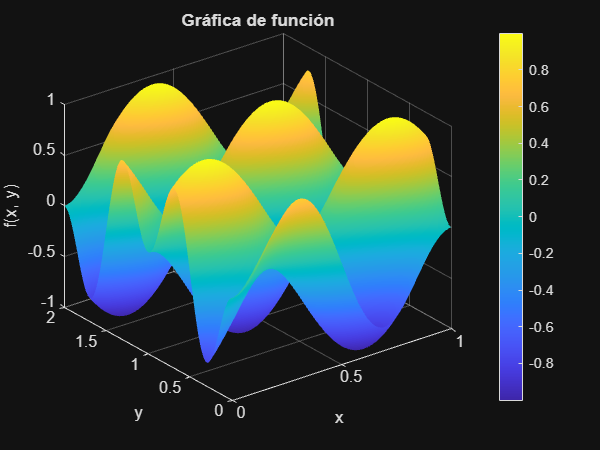

surf(xx, yy, f);
colorbar;        % Para agregar colores de niveles
shading interp;  % Para que no se vea la maya
view(3);         % Ajustar la vista en 3D
xlabel('x');
ylabel('y');
zlabel('f(x, y)'); 
title('Gráfica de función');

## b)

Calcular la función f(x, y) en la malla y asignarla a zz de esta manera, ya que zz=f(xx,yy) me da problemas

zz = sin(2 * pi * (xx + yy)) .* sin(pi * (xx - yy));


Obtener la descomposición en valores singulares de zz

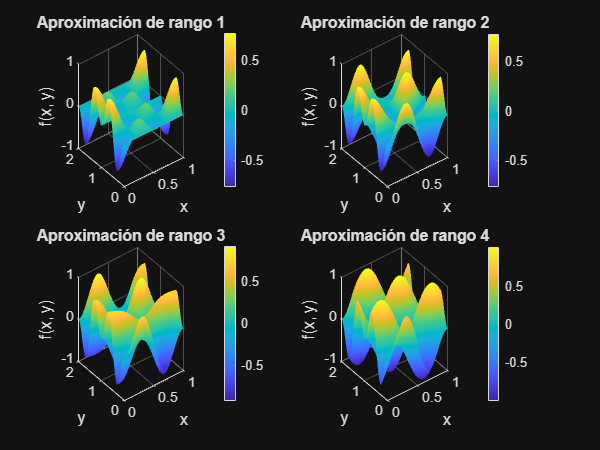

[U, S, V] = svd(zz);

% Crear subgráficas de las mejores aproximaciones 4
figure;
for k = 1:4
    % Aproximación de rango k
    zz_k = U(:, 1:k) * S(1:k, 1:k) * V(:, 1:k)';
    
    subplot(2, 2, k);
    surf(xx, yy, zz_k);
    colorbar;
    shading interp;
    view(3);
    xlabel('x');
    ylabel('y');
    zlabel('f(x, y)');
    title(['Aproximación de rango ', num2str(k)]);
end

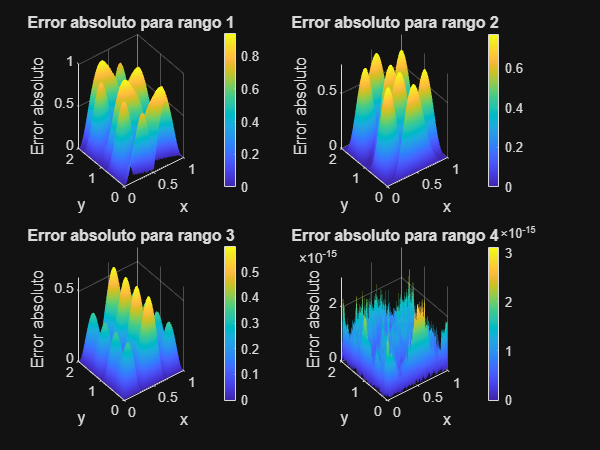


% Graficar el error absoluto para cada aproximación
figure;
for k = 1:4
    % Error absoluto
    zz_k = U(:, 1:k) * S(1:k, 1:k) * V(:, 1:k)';
    error_abs = abs(zz - zz_k);
    
    subplot(2, 2, k);
    surf(xx, yy, error_abs);
    colorbar;
    shading interp;
    view(3);
    xlabel('x');
    ylabel('y');
    zlabel('Error absoluto');
    title(['Error absoluto para rango ', num2str(k)]);
end

## c)

Mostrar los valores singulares

% Se usa un for para que muestre mas decimales
for i = 1:6
    fprintf('%20.16f\n', S(i, i)); 
end

 35.7919334487535039
 35.4409720521319684
 35.0900626958687667
 35.0900626958687667
  0.0000000000000318
  0.0000000000000190


Dado que a partir del cuarto valor singular son número muy cercanos a cero, solo se consideran los primeros 4 valores.

Para ver el rango de zz utilizamos la función rank:

disp(rank(zz))

     4



## d)

A partir de la función dada y aplicando porpiedades de senos:


$$f(x, y) = \sin\left(2 \pi (x + y)\right) \sin\left(\pi (x - y)\right)  = \left( \sin(2 \pi x) \cos(2 \pi y) + \sin(2 \pi y) \cos(2 \pi x) \right) \cdot \left( \sin(\pi x) \cos(\pi y) - \sin(\pi y) \cos(\pi x) \right)

$$
 

Al evaluar en la función los vectores $xx 
$ y $yy$ se tiene la expresión que representa la matriz $zz$:


$$zz = \sin(2 \pi x) \cdot \sin(\pi x) \left( \cos(2 \pi y) \cos(\pi y) \right)^T - \sin(2 \pi x) \cos(\pi x) \cdot \left( \cos(2 \pi y) \sin(\pi y) \right)^T

$$


       
$$+ \sin(\pi x) \cdot \cos(2 \pi x) \left( \sin(2 \pi y) \cos(\pi y) \right)^T - \cos(2 \pi x) \cos(\pi x) \left( \sin(2 \pi y) \sin(\pi y) \right)^T$$


Al normalizar los vectores, se obtienen los vectores unitarios:


$$zz= || \sin(2 \pi x) \sin(\pi x) || \cdot|| \cos(2 \pi y) \cos(\pi y) || \cdot 
\left( \frac{\sin(2 \pi x) \sin(\pi x)}{|| \sin(2 \pi x) \sin(\pi x) ||} \right)
\left( \frac{\cos(2 \pi y) \cos(\pi y)}{|| \cos(2 \pi y) \cos(\pi y) ||} \right)^T \\$$


       
$$- || \sin(2 \pi x) \cos(\pi x) ||\cdot|| \cos(2 \pi y) \sin(\pi y) ||\cdot 
\left( \frac{\sin(2 \pi x) \cos(\pi x)}{|| \sin(2 \pi x) \cos(\pi x) ||} \right)
\left( \frac{\cos(2 \pi y) \sin(\pi y)}{|| \cos(2 \pi y) \sin(\pi y) ||} \right)^T \\
$$


       
$$
+  || \sin(2 \pi y) \cos(\pi y) ||\cdot|| \sin(\pi x) \cos(2 \pi x) || \cdot 
\left( \frac{\sin(\pi x) \cos(2 \pi x)}{|| \sin(\pi x) \cos(2 \pi x) ||} \right)
\left( \frac{\sin(2 \pi y) \cos(\pi y)}{|| \sin(2 \pi y) \cos(\pi y) ||} \right)^T \\


$$


       
$$- || \sin(2 \pi y) \sin(\pi y) ||\cdot|| \cos(2 \pi x) \cos(\pi x) || \cdot 
\left( \frac{\cos(2 \pi x) \cos(\pi x)}{|| \cos(2 \pi x) \cos(\pi x) ||} \right)
\left( \frac{\sin(2 \pi y) \sin(\pi y)}{|| \sin(2 \pi y) \sin(\pi y) ||} \right)^T$$


Según el lema 5.19 se tiene $A = \sum_{j=1}^{r} \sigma_j u_j v_j^*
$ donde $\{ u_j \}_{j=1}^{r} 
$ y $ \{ v_j \}_{j=1}^{r}$ son los vectores singulares izquierdos y derechos,

respectivamente, por ende pertenecen al espacio de filas y columnas respectivamente y $ \{ \sigma_j \}_{j=1}^{r}$ son escalares. Note que podemos expresar la matriz $zz$ como el lema, si tomamos los $\sigma_j$ como las normas al inicio de cada sumando que representan la magnitud o peso a cada componente de rango 1, los vectores dependientes de $x$ como los $u_j$, ya que estos son del espacio filas y por último los vectoes transpuestos (para que se obtenga la matriz) dependientes de $y$ se toman como los $v_j$. Dado que con este lema la cantidad de sumandos indican el rango de la matriz, entonces se concluye que es rango 4.